% Expand Fourier series of periodic functions f(x) with period T, 
% given on the indicated intervals:
% f(x)=-h on [-pi;0]
%       h  on [0;pi]
% T=2*pi;

clear
pi1=pi;
syms x h real;
syms pi;
% h=1
f(x)=piecewise(-pi<x<0,-h,0<=x<pi,h)

$$f(x) = \left\{ \begin{array}{cl} -h & \text{ if }x\in \left(-\pi ,0\right)\\ h & \text{ if }x\in \left[0,\pi \right) \end{array}\right.$$

% fplot(f(x),[-pi1 pi1]);

syms m integer;
assume(m>=1)
[a0,a(m),b(m),abf(m)]=fourierseries(f)

$$a0 = 0$$

$$a(m) = 0$$

$$b(m) = -\frac{2\,h\,\left({\left(-1\right)}^{m}-1\right)}{m\,\pi }$$

$$abf(m) = -\frac{2\,h\,\sin\left(m\,x\right)\,\left({\left(-1\right)}^{m}-1\right)}{m\,\pi }$$


% fplot(f(x),[-pi1 pi1]);
% grid on
% hold on

f1=a0/2;
for m=1:5
    m1(m)=m;
    a1(m)=a(m);
    b1(m)=b(m);
    abf1(m)=abf(m);
    f1=f1+abf(m);
    % fplot(f1,[-pi1 pi1])
    % grid on
end
% hold off

a0/2

$$ans = 0$$

% 0
ft=[m1;a1;b1;abf1];
ft'

$$ans = \left(\begin{array}{cccc} 1 & 0 & \frac{4\,h}{\pi } & \frac{4\,h\,\sin\left(x\right)}{\pi }\\ 2 & 0 & 0 & 0\\ 3 & 0 & \frac{4\,h}{3\,\pi } & \frac{4\,h\,\sin\left(3\,x\right)}{3\,\pi }\\ 4 & 0 & 0 & 0\\ 5 & 0 & \frac{4\,h}{5\,\pi } & \frac{4\,h\,\sin\left(5\,x\right)}{5\,\pi } \end{array}\right)$$

% [ 1, 0,     (4*h)/pi,       (4*h*sin(x))/pi]
% [ 2, 0,            0,                     0]
% [ 3, 0, (4*h)/(3*pi), (4*h*sin(3*x))/(3*pi)]
% [ 4, 0,            0,                     0]
% [ 5, 0, (4*h)/(5*pi), (4*h*sin(5*x))/(5*pi)]

f(x)=subs(f(x),h,1)

$$f(x) = \left\{ \begin{array}{cl} -1 & \text{ if }x\in \left(-\pi ,0\right)\\ 1 & \text{ if }x\in \left[0,\pi \right) \end{array}\right.$$

fplot(f(x),[-pi1 pi1]);
grid on
hold on

syms m;
abf2(m)=4*h*sin((2*m-1)*x)/((2*m-1)*pi)

$$abf2(m) = \frac{4\,h\,\sin\left(x\,\left(2\,m-1\right)\right)}{\pi \,\left(2\,m-1\right)}$$

abf2(m)=subs(abf2(m),h,1)

$$abf2(m) = \frac{4\,\sin\left(x\,\left(2\,m-1\right)\right)}{\pi \,\left(2\,m-1\right)}$$

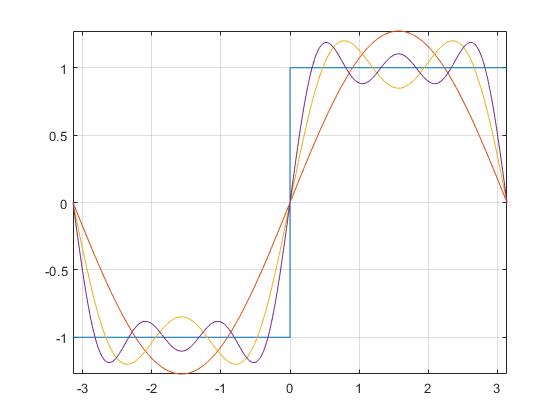


f3=a0/2;
for m=1:3
    m3(m)=m;
    abf3(m)=abf2(m);
    f3=f3+abf3(m);
    fplot(f3,[-pi1 pi1])
    grid on    
end
hold off

ft3=[m3;abf3];
ft3'

$$ans = \left(\begin{array}{cc} 1 & \frac{4\,\sin\left(x\right)}{\pi }\\ 2 & \frac{4\,\sin\left(3\,x\right)}{3\,\pi }\\ 3 & \frac{4\,\sin\left(5\,x\right)}{5\,\pi } \end{array}\right)$$

% [ 1,       (4*sin(x))/pi]
% [ 2, (4*sin(3*x))/(3*pi)]
% [ 3, (4*sin(5*x))/(5*pi)]